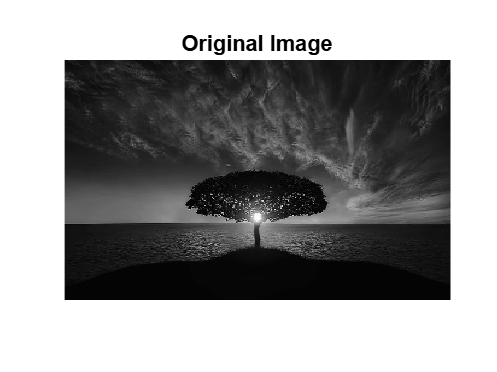

clc;
clear;
close all;

% Read the input image
image = imread('https://cdn.pixabay.com/photo/2015/04/23/22/00/tree-736885_1280.jpg'); % Replace with your image
grayImage = rgb2gray(image); % Convert to grayscale for simplicity

% Display the original image
figure;
imshow(grayImage);
title('Original Image');


% Parameters
blockSize = 8; % Block size (8x8)
Q = [16 11 10 16 24 40 51 61;   % Quantization matrix
     12 12 14 19 26 58 60 55;
     14 13 16 24 40 57 69 56;
     14 17 22 29 51 87 80 62;
     18 22 37 56 68 109 103 77;
     24 35 55 64 81 104 113 92;
     49 64 78 87 103 121 120 101;
     72 92 95 98 112 100 103 99];

[rows, cols] = size(grayImage);

% Ensure dimensions are divisible by block size
paddedRows = ceil(rows / blockSize) * blockSize;
paddedCols = ceil(cols / blockSize) * blockSize;
paddedImage = uint8(zeros(paddedRows, paddedCols));
paddedImage(1:rows, 1:cols) = grayImage;

encodedImage = zeros(paddedRows, paddedCols); % Initialize the encoded image

% JPEG Encoder with Zigzag Scan
disp('Encoding...');

Encoding...


for i = 1:blockSize:paddedRows
    for j = 1:blockSize:paddedCols
        block = double(paddedImage(i:i+blockSize-1, j:j+blockSize-1)) - 128; % Center range around 0
        dctBlock = dct2(block); % Apply DCT
        quantizedBlock = round(dctBlock ./ Q); % Quantization
        zigzagBlock = zigzag(quantizedBlock); % Zigzag scan to 1D
        % Store the 1D zigzag block back into the encoded image
        encodedImage(i:i+blockSize-1, j:j+blockSize-1) = reshape(zigzagBlock, [blockSize, blockSize]);
    end
end

% JPEG Decoder with Inverse Zigzag
disp('Decoding...');

Decoding...


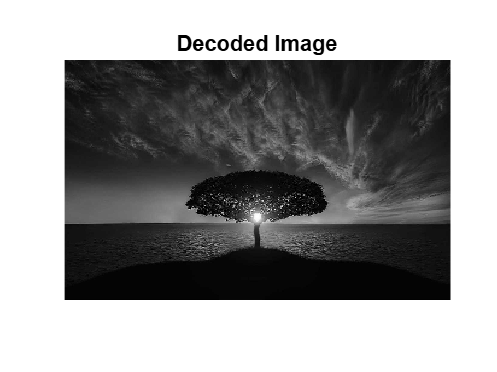

decodedImage = zeros(size(encodedImage));
for i = 1:blockSize:paddedRows
    for j = 1:blockSize:paddedCols
        zigzagBlock = reshape(encodedImage(i:i+blockSize-1, j:j+blockSize-1), [1, 64]); % Get the 1D zigzag block
        quantizedBlock = inverse_zigzag(zigzagBlock); % Inverse zigzag to 8x8 block
        dequantizedBlock = quantizedBlock .* Q; % Dequantization
        idctBlock = idct2(dequantizedBlock) + 128; % Inverse DCT
        decodedImage(i:i+blockSize-1, j:j+blockSize-1) = idctBlock;
    end
end

decodedImage = uint8(decodedImage(1:rows, 1:cols)); % Remove padding

% Display the decoded image
figure;
imshow(decodedImage);
title('Decoded Image');


% Calculate PSNR
mse = mean((double(grayImage(:)) - double(decodedImage(:))).^2);
psnrValue = 10 * log10(255^2 / mse);
disp(['PSNR: ', num2str(psnrValue), ' dB']);

PSNR: 36.314 dB



% Supporting Functions

function zigzagIndices = zigzag(block)
    % Zigzag scan for 8x8 block
    zigzagOrder = [
        1 2 4 7 8 9 5 3 6 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64
    ];
    zigzagIndices = block(zigzagOrder); % Convert 8x8 to 1D
end

function block = inverse_zigzag(zigzagIndices)
    % Inverse zigzag scan to reconstruct 8x8 block
    inverseZigzagOrder = [
        1 2 4 7 8 9 5 3 6 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64
    ];
    block = zeros(8, 8);
    block(inverseZigzagOrder) = zigzagIndices; % Rebuild 8x8 from 1D
end
